clc
clear all
close all
t=1:0.01:10;
t=-4:0.01:4;
T=4'

T = 4

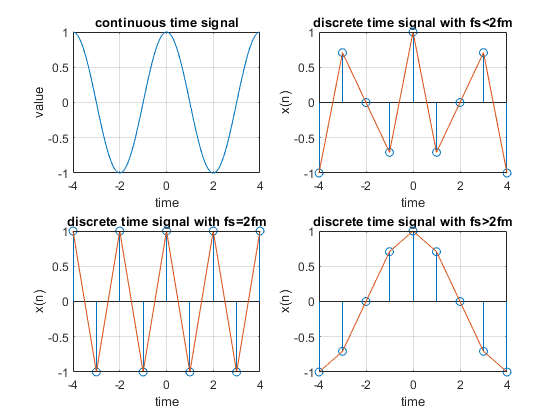

fm=1/T;
x=cos(2*pi*fm*t); %input signal
subplot(2,2,1);
plot(t,x);
xlabel('time'); ylabel('value'); title('continuous time signal');
grid on;
n1=-4:4;
fs1 = 1.6*fm;
fs2 = 2*fm;
fs3 = 8*fm;
%discrete time signal with fs<2fm
x1 = cos(2*pi*fm/fs1*n1);
subplot(2,2,2);
stem(n1,x1);
xlabel('time'); ylabel('x(n)'); title('discrete time signal with fs<2fm');
hold on;
subplot(2,2,2);
plot(n1,x1);
grid on;
%discrete time signal with fs=2fm
n2=-5:5;
x2 = cos(2*pi*fm/fs2*n1);
subplot(2,2,3);
stem(n1,x2);
xlabel('time'); ylabel('x(n)'); title('discrete time signal with fs=2fm');
hold on;
subplot(2,2,3);
plot(n1,x2);
grid on;
%discrete time signal with fs>2fm
n3=-20:20;
x3 = cos(2*pi*fm/fs3*n1);
subplot(2,2,4);
stem(n1,x3);
xlabel('time'); ylabel('x(n)'); title('discrete time signal with fs>2fm');
hold on;
subplot(2,2,4);
plot(n1,x3);
grid on;

%sampling methods

clc;
clear all;
close all;
t=0:0.01:3;
a=sin(2*pi*t); %message signal
p=square(2*pi*10*t); %carrier signal
p(p<0)=0;
s=a.*p;
subplot(4,1,1);
plot(t,a);
xlabel('time'); ylabel('amplitude'); title('message signal');
subplot(4,1,2);
plot(t,p);
xlabel('time'); ylabel('amplitude'); title('carrier signal');
subplot(4,1,3);
plot(t,s);
xlabel('time'); ylabel('amplitude'); title('natural sampling');
y=uencode(s,3,1);
disp(s);

  Columns 1 through 12

         0    0.0628    0.1253    0.1874    0.2487         0         0         0         0         0    0.5878    0.6374

  Columns 13 through 24

    0.6845    0.7290    0.7705         0         0         0         0         0    0.9511    0.9686    0.9823    0.9921

  Columns 25 through 36

    0.9980         0         0         0         0         0    0.9511    0.9298    0.9048    0.8763    0.8443         0

  Columns 37 through 48

         0         0         0         0    0.5878    0.5358    0.4818    0.4258    0.3681         0         0         0

  Columns 49 through 60

         0         0    0.0000   -0.0628   -0.1253   -0.1874   -0.2487         0         0         0         0         0

  Columns 61 through 72

   -0.5878   -0.6374   -0.6845   -0.7290   -0.7705         0         0         0         0         0   -0.9511   -0.9686

  Columns 73 through 84

   -0.9823   -0.9921   -0.9980   -1.0000         0         0         0         0   -0.9511   -

disp(y);

  Columns 1 through 31

   4   4   4   4   4   4   4   4   4   4   6   6   6   6   7   4   4   4   4   4   7   7   7   7   7   4   4   4   4   4   7

  Columns 32 through 62

   7   7   7   7   4   4   4   4   4   6   6   5   5   5   4   4   4   4   4   4   3   3   3   3   4   4   4   4   4   1   1

  Columns 63 through 93

   1   1   0   4   4   4   4   4   0   0   0   0   0   0   4   4   4   4   0   0   0   0   0   0   4   4   4   4   1   1   2

  Columns 94 through 124

   2   2   4   4   4   4   4   3   4   4   4   4   4   4   4   4   4   6   6   6   6   7   4   4   4   4   4   7   7   7   7

  Columns 125 through 155

   7   4   4   4   4   4   7   7   7   7   7   4   4   4   4   4   6   6   5   5   5   4   4   4   4   4   4   3   3   3   3

  Columns 156 through 186

   2   4   4   4   4   1   1   1   1   0   0   4   4   4   4   0   0   0   0   0   0   4   4   4   4   0   0   0   0   0   0

  Columns 187 through 217

   4   4   4   4   1   1   2   2   2   2   4   4   4   4   3   

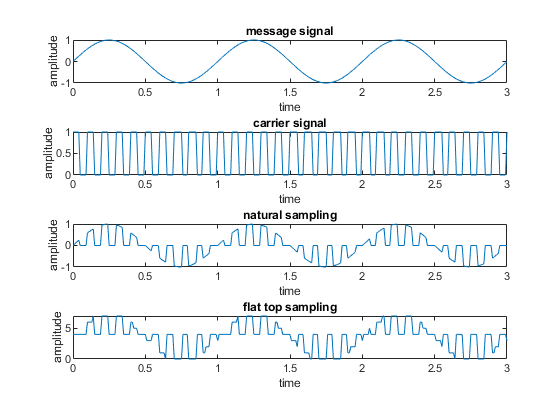

subplot(4,1,4);
plot(t,y);
xlabel('time'); ylabel('amplitude'); title('flat top sampling');

%sampling methods

clc;
clear all;
close all;
t=-4:0.01:4;
a=cos(2*pi*t); %message signal
p=square(2*pi*10*t); %carrier signal
p(p<0)=0;
s=a.*p;
subplot(4,1,1);
plot(t,a);
xlabel('time'); ylabel('amplitude'); title('message signal');
subplot(4,1,2);
plot(t,p);
xlabel('time'); ylabel('amplitude'); title('carrier signal');
subplot(4,1,3);
plot(t,s);
xlabel('time'); ylabel('amplitude'); title('natural sampling');
y=uencode(s,3,1);
disp(s);

    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511         0         0         0         0    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878         0         0         0         0    0.3090    0.2487    0.1874    0.1253    0.0628         0         0         0         0         0   -0.3090   -0.3681   -0.4258   -0.4818   -0.5358         0         0         0         0         0   -0.8090   -0.8443   -0.8763   -0.9048   -0.9298         0         0         0         0         0   -1.0000   -0.9980   -0.9921   -0.9823   -0.9686   -0.9511         0         0         0         0   -0.8090   -0.7705   -0.7290   -0.6845   -0.6374         0         0         0         0         0   -0.3090   -0.2487   -0.1874   -0.1253   -0.0628         0         0         0         0         0    0.3090    0.3681    0.4258    0.4818    0.5358         0         0         0         0         0    0.8090    0.8443    0.8763    0.9048    0.9298         0         0         0         0         0

disp(y);

   7   7   7   7   7   7   4   4   4   4   7   7   6   6   6   6   4   4   4   4   5   4   4   4   4   4   4   4   4   4   2   2   2   2   1   4   4   4   4   4   0   0   0   0   0   4   4   4   4   4   0   0   0   0   0   0   4   4   4   4   0   0   1   1   1   4   4   4   4   4   2   3   3   3   3   4   4   4   4   4   5   5   5   5   6   4   4   4   4   4   7   7   7   7   7   4   4   4   4   4   7   7   7   7   7   7   4   4   4   4   7   7   6   6   6   4   4   4   4   4   5   4   4   4   4   3   4   4   4   4   2   2   2   2   1   1   4   4   4   4   0   0   0   0   0   4   4   4   4   4   0   0   0   0   0   0   4   4   4   4   0   0   1   1   1   4   4   4   4   4   2   3   3   3   3   4   4   4   4   4   5   5   5   5   6   4   4   4   4   4   7   7   7   7   7   4   4   4   4   4   7   7   7   7   7   7   4   4   4   4   7   7   6   6   6   6   4   4   4   4   5   4   4   4   4   4   4   4   4   4   2   2   2   2   1   4   4   4   4   4   0   0   0   0   0   4   4   4   4   4

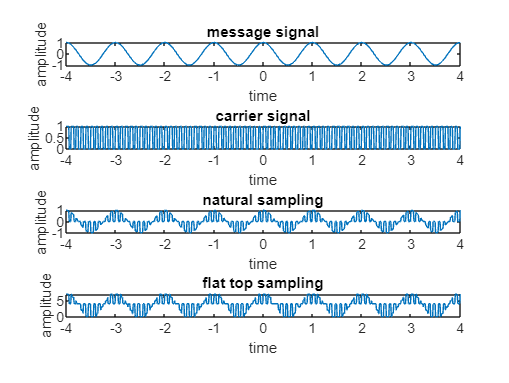

subplot(4,1,4);
plot(t,y);
xlabel('time'); ylabel('amplitude'); title('flat top sampling');

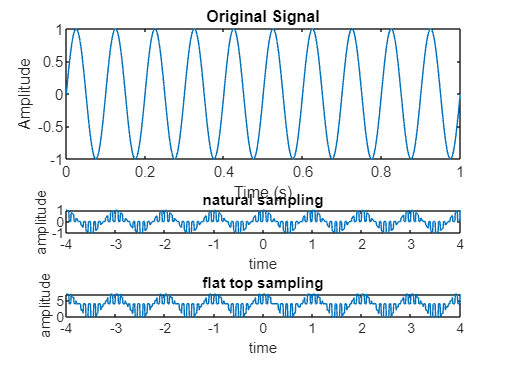

% Create a continuous-time signal
t = 0:0.001:1; % Time vector
x = sin(2*pi*10*t); % Signal with a frequency of 10 Hz

% Perform ideal sampling
Fs = 100; % Desired sampling rate
Ts = 1/Fs; % Sampling period
n = 0:Ts:1; % Sampled time vector
x_sampled = interp1(t, x, n, 'nearest'); % Perform ideal sampling

% Plot the original and sampled signals
subplot(2,1,1);
plot(t, x);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

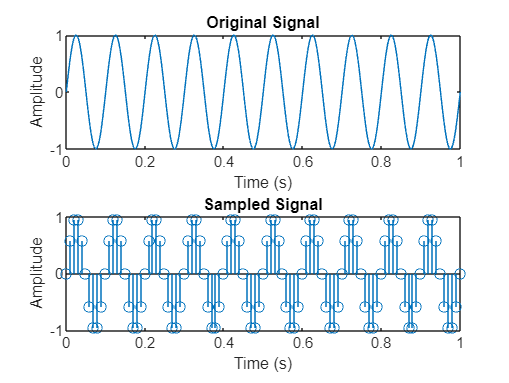


subplot(2,1,2);
stem(n, x_sampled);
title('Sampled Signal');
xlabel('Time (s)');
ylabel('Amplitude');

doc interp1